# **IO723 - CAN Loopback**

This example shows you how to configure the IO723 I/O module and select signals from the linked database using a CAN loopback between channel one and two.

The IO723 is a configurable Restbus simulation I/O module supporting CAN-FD and 100/1000 Base-T1 interfaces.

The Simulink model features the [IO723 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io723_setup), [IO723 Read Interface](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io723_read_interface), and [IO723 Write Interface](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io723_write_interface) blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO723 I/O module installed

- CAN Splitter-cable (8-Pin Male M9 Binder to 2x 9-Pin Female D-sub)

- Termination for the CAN bus ends

- Gender changer for 9-Pin D-sub connector

### Test Setup

In this example, data is sent from one CAN channel of the IO723 to the other CAN channel, both located on the same connector (In this example connector 5 at the very bottom of the module is used). Please check the FL3X project for more details about the channel layout and the configured bus setting like bus speed.

The delivered CAN Splitter-cable can be directly connected to the IO723 and be used as loopback by connecting the D-sub connectors together. Please use the included termination adapters on both ends of the D-sub connectors for bus termination. A gender changer adapter is required to complete the loopback.

For detailed pin mapping of the D-sub connector, please refer to the [IO723 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io723_pin_mapping) in the documentation. 

## Initialize and Open the Simulink Model

 
% Unzip FL3X configuration project
unzip('FL3X_CANLoopback.zip');

% Open Simulink model
modelName = 'sgMdl_IO723_CANLoopback';
open_system(modelName);

### Model Description

In the model, a sine wave signal is used for each of the two selected signals and grouped into a bus by the [Bus Creator](https://www.mathworks.com/help/simulink/slref/buscreator.html) block. These input signals are visible in the [IO723 Write Interface](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io723_write_interface) application, where they must be mapped to the desired signal from the database to be transmitted. On the receiving side, the signals of interest must be selected in the [IO723 Read Interface](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io723_read_interface) block. By using the [Bus Selector](https://www.mathworks.com/help/simulink/slref/busselector.html) block, the individual signals can get extracted from the bus and displayed by the scope.

The block cycle time defines the cycle time of all connected signals. The timing information of each signal can be looked up in the respective Interface application or the FL3X project. The IO723 updates the signal values on the bus according to the setting in the FL3X configuration project and not the selected block sample time. The IO723 Simulink blocks just update the signal values in the memory of the IO723 and not directly on the connected bus. The project running on the IO723 handles the data exchange independently from the Simulink model.

The required signal information is stored in an external configuration project generated by FL3X Config software, which is available in this example. (FL3X_CANLoopback)

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode
% set_param(modelName,'SimulationCommand','start')      % start real-time application through Simulink toolstrip

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check that the loopback is working as expected, open the Simulink scope connected to the [Bus Selector](https://www.mathworks.com/help/simulink/slref/busselector.html) block. In the scope, two sine wave signals must be displayed: one with an amplitude of 10 and the other one with an amplitude of 20.

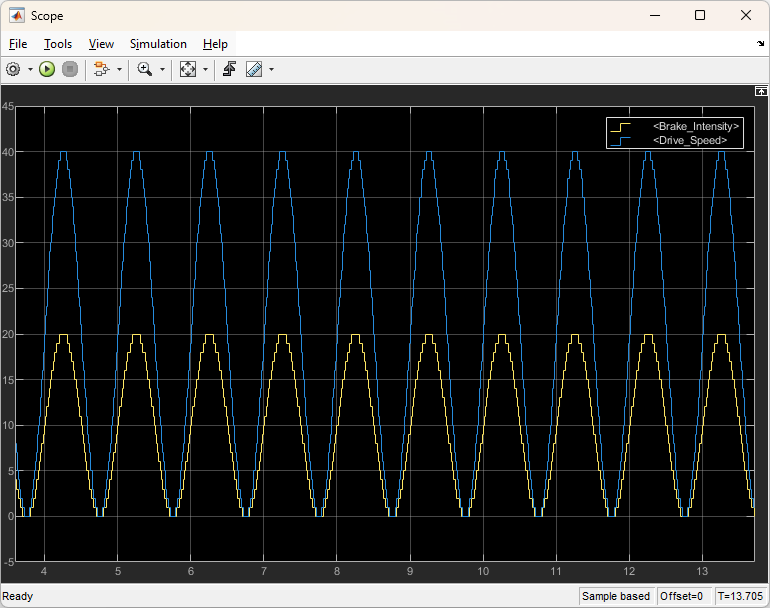

## Additional References

- [IO723 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io723)